clear; clc; close all

%% 1. PARAMÈTRES
dossier_mere = 'E:\Data\Aurelie\analysis\Final\assembly\cues\';

% Liste des variables à extraire de brainbow.mat et à sauvegarder
liste_vars_results = {'identifier', 'F', 'sampling_rate', 'speed', 'position', 'path'};

%% 2. RECHERCHE DE TOUS LES FICHIERS BRAINBOW.MAT
fprintf('Recherche des fichiers brainbow.mat...\n');

Recherche des fichiers brainbow.mat...


tous_les_fichiers = dir(fullfile(dossier_mere, '**', 'k6', 'results.mat'));

fprintf('%d fichiers trouvés. Analyse en cours...\n\n', length(tous_les_fichiers));

44 fichiers trouvés. Analyse en cours...



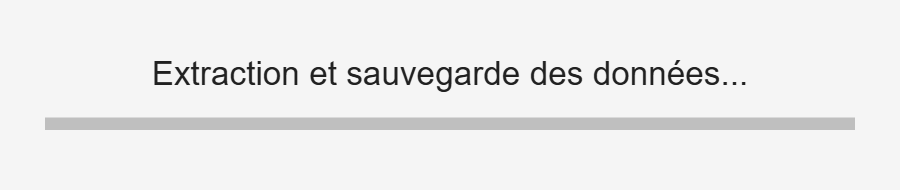


%% 3. EXTRACTION ET SAUVEGARDE EN BOUCLE
h_wait = waitbar(0, 'Extraction et sauvegarde des données...', 'Name', 'Progression');

for i = 1:length(tous_les_fichiers)
    dossier_actuel = tous_les_fichiers(i).folder;
    chemin_bb = fullfile(dossier_actuel, 'results.mat');
    
    try
        % --- 3.1 CHARGEMENT DYNAMIQUE DE BRAINBOW.MAT ---
        res = load(chemin_bb, liste_vars_results{:});
        
        % --- 3.2 CRÉATION DE LA VARIABLE DATA_RECORDING ---
        data_recording = struct(); % Initialisation de la structure
        
        for v = 1:length(liste_vars_results)
            nom_var = liste_vars_results{v};
            if isfield(res, nom_var)
                data_recording.(nom_var) = res.(nom_var); % Écriture dynamique
            else
                data_recording.(nom_var) = []; % Met du vide si non trouvé
            end
        end
        
        % --- 3.3 DÉTERMINATION DU DOSSIER DE SAUVEGARDE ET ÉCRITURE ---
        % Si la variable 'path' extraite est un chemin de dossier valide, on l'utilise
        if isfield(data_recording, 'path') && (ischar(data_recording.path) || isstring(data_recording.path)) && exist(char(data_recording.path), 'dir')
            dossier_sauvegarde = char(data_recording.path);
        else
            % Sinon, on utilise le dossier où se trouve le brainbow.mat
            dossier_sauvegarde = dossier_actuel; 
        end
        
        chemin_save_local = fullfile(dossier_sauvegarde, 'data_recording.mat');
        
        % Sauvegarde de la structure data_recording dans le dossier cible
        save(chemin_save_local, 'data_recording');
        
        % Nettoyage de la RAM pour éviter de saturer la mémoire (important pour F)
        clear('data_recording', 'res');
        
    catch exception
        fprintf('⚠️ Erreur sur %s : %s\n', chemin_bb, exception.message);
    end
    
    waitbar(i / length(tous_les_fichiers), h_wait, sprintf('Extraction et Écriture : %d/%d', i, length(tous_les_fichiers)));
end


close(h_wait);
fprintf('✅ TOUT EST FINI ! Fichiers data_recording.mat créés avec succès.\n');

✅ TOUT EST FINI ! Fichiers data_recording.mat créés avec succès.
